# Определение нот композиции по суммам

clear all
close all

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:6);
Tab_F = k' .* repmat(Tab_F_1, 7, 1);

M = zeros(7, 12);
Ms = M;

Samples_num = 1024;

path = 'D:\Desktop\Studie\Diploma\Audio data\wav\60 нот.wav';
[y, Fs] = audioread(path);
z = y(:,1);

cuts = floor( length(z) / Samples_num ) - 1;    % Кол-во вырезок по времени
notes_lin = zeros(1, cuts);
k_interp = Fs/Samples_num - 1;
zeros_num = floor( k_interp*Samples_num );
Zer = zeros(zeros_num, 1);
L2 = ( (k_interp+1)*Samples_num);
Indexes = floor(L2 * Tab_F / Fs + 1);   % NOT FLAT!!!

v1 = [1 1 1 1 1 1 1] * 1/7;
v2 = [0 1 0 1 0 1 0] * 1/3;
v3 = [0 0 1 0 0 1 0] * 1/2;
v4 = [0 0 0 1 0 0 1] * 1/2;
v5 = [0 0 0 0 1 0 0]; 
v6 = [0 0 0 0 0 1 0];
v7 = [0 0 0 0 0 0 1];

V = [v1; v2; v3; v4; v5; v6; v7];

Очистка

clear path y Tab_F_1 k v1 v2 v3 v4 v5 v6 v7

Находим ноты

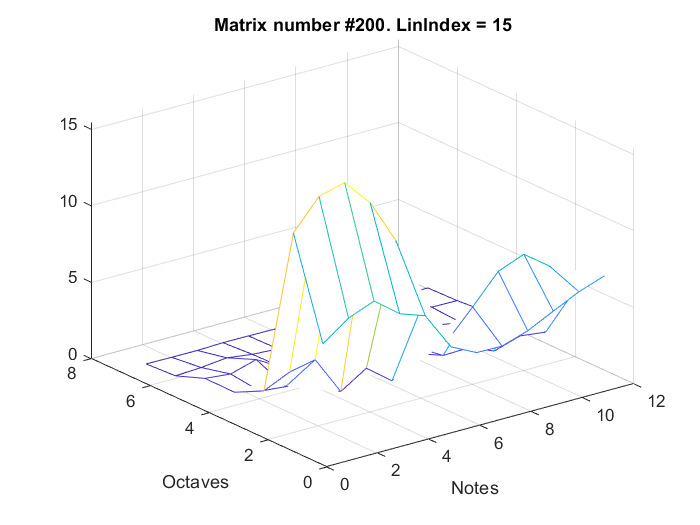

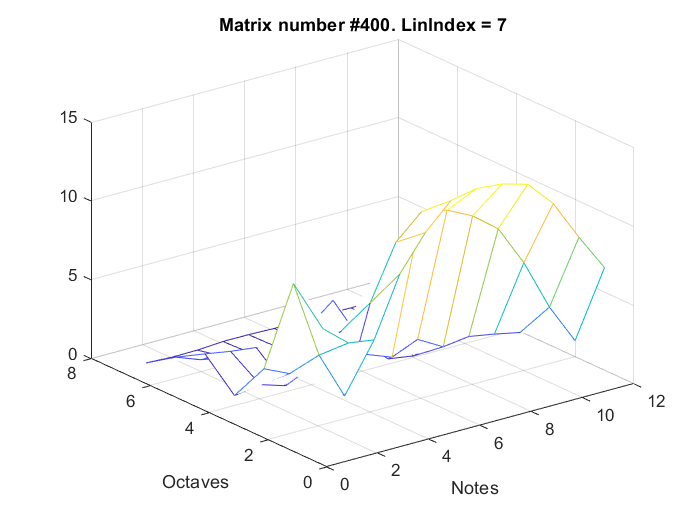

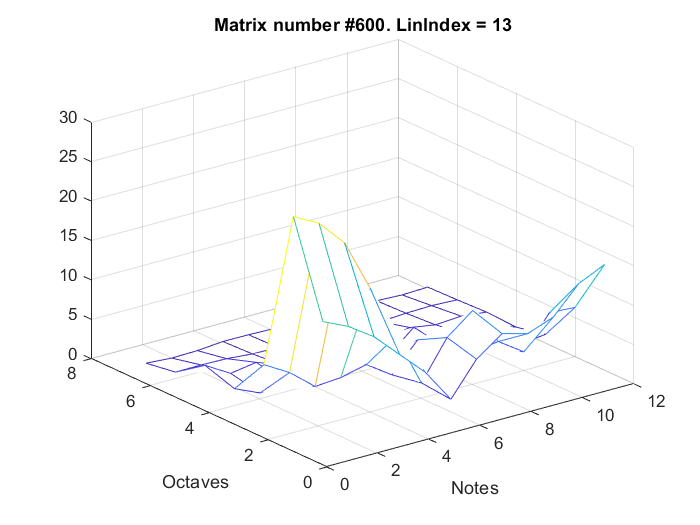

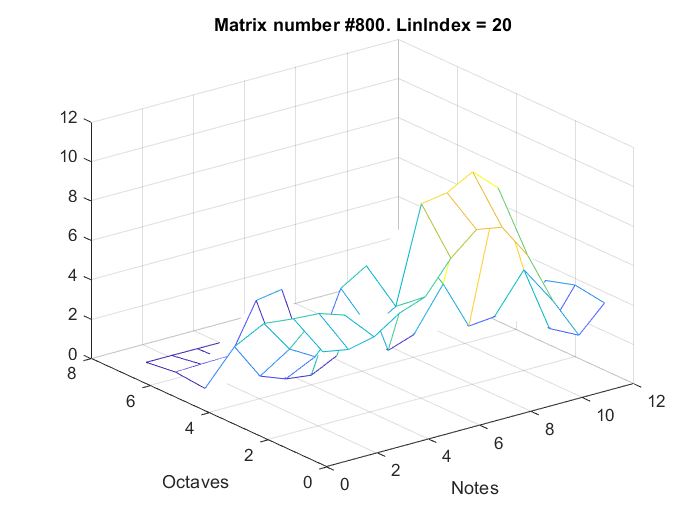

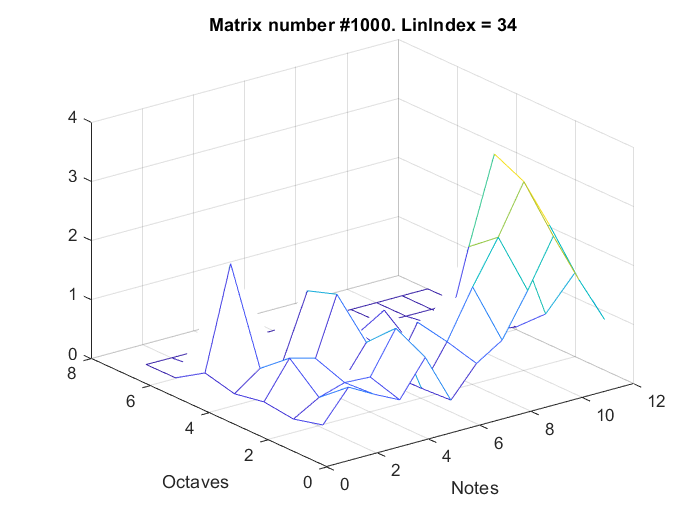

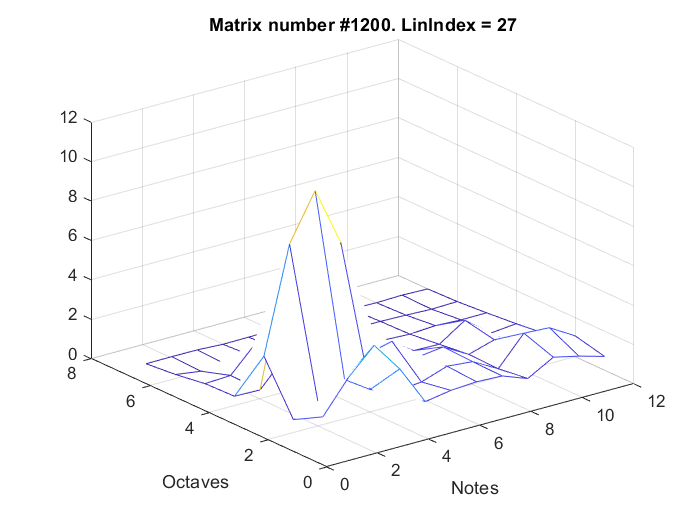

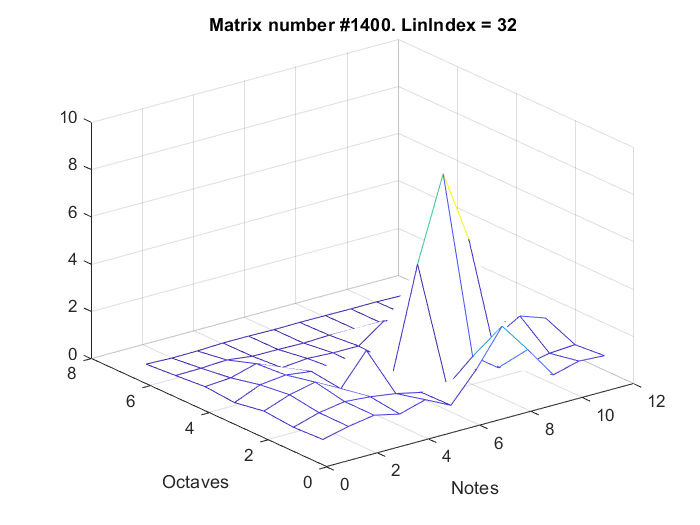

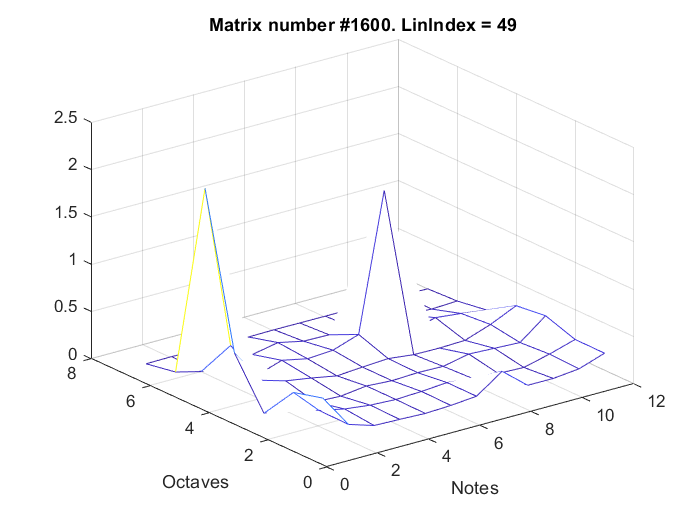

for i = 1:cuts
    
    n1 = i*Samples_num;         % Задаю пределы для вырезания участка сигнала
    n2 = (i+1)*Samples_num - 1;
    
    S = z(n1: n2);              % Берем участок сигнала
    S2 = vertcat (Zer, S);      % Интерполируем спектр
    Spec = abs(fft(S2));        % Находим спектр сигнала
    M = Spec(Indexes);          % Заполняем матрицу нот
    
    Ms = V * M;
    
    [Val, Ind] = max(Ms',[],[1 2], 'linear');   % Нахожу индекс максимума
    
    notes_lin(i) = Ind;         % Сохраняю текущую ноту
    
    if mod(i,200) == 0
        figure(i)
        mesh(Ms);
        xlabel("Notes")
        ylabel("Octaves")
        title("Matrix number #" + string(i) + ". LinIndex = " + string(Ind))
    end
    
end

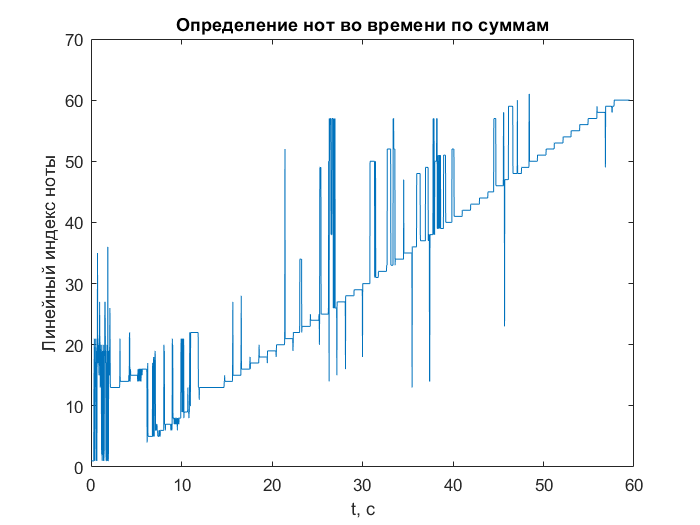


t = (1:cuts) * Samples_num / Fs;
plot(t, notes_lin)
xlabel("t, c")
ylabel("Линейный индекс ноты")
title("Определение нот во времени по суммам")